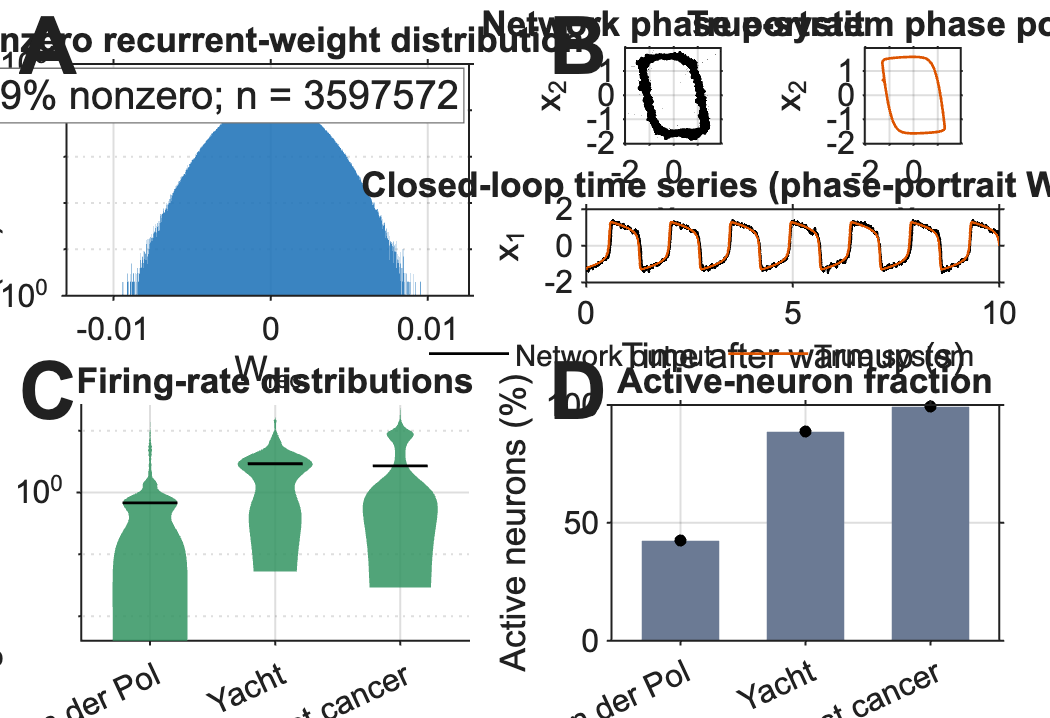

Exported full-rank publication figure PNG: /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/shared/plotting/publication_figures/generated_full_rank_figure/full_rank_network_publication_figure.png


%% Sparse Full-Rank Network Publication Figure
% This figure loads saved full-rank proof-network tests only. It never
% retrains or re-evaluates a network, and it deliberately never densifies
% the 6000 x 6000 sparse recurrent matrix.

clear; clc; close all;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

%% Configuration
cfg = struct();
cfg.analysis_dir = fullfile(repo_root, 'outputs', 'publication_analysis');
cfg.preferred_backend = 'gpu';
cfg.task_ids = {'dynamical_systems_vanderpol_full_rank6k', ...
    'regression_yacht_full_rank6k', 'classification_BC_full_rank6k'};
cfg.task_labels = {'Van der Pol', 'Yacht', 'Breast cancer'};
cfg.required_n_hidden = 6000;
cfg.display_seed = 1; % The available full-rank proof analyses currently use seed 1.
cfg.minimum_summary_seed_count = 1; % Raise to 3 after three full-rank seeds are tested.
cfg.weight_histogram_bins = 1e3;
cfg.weight_histogram_x_scale = 'linear';
cfg.weight_histogram_y_scale = 'log';
cfg.weight_histogram_color = [0.12 .45 .72];
cfg.weight_histogram_face_alpha = .88;
cfg.phase_stride = 5;
cfg.time_window_s = 10;
cfg.rate_distribution_y_scale = 'log';
cfg.violin_max_width = .30;
cfg.violin_face_alpha = .85;
cfg.font_name = 'Arial';
cfg.tick_font_size = 12;
cfg.label_font_size = 15;
cfg.title_font_size = 18;
cfg.line_width = 1.0;
cfg.axes_line_width = .75;
cfg.tick_direction = 'out';
cfg.show_grid = true;
cfg.network_color = [0 0 0];
cfg.truth_color = [0.8660 0.3290 0.0000];
cfg.rate_color = [0.20 0.58 0.38];
cfg.active_color = [0.42 0.48 0.58];
cfg.median_color = [0 0 0];
cfg.summary_point_color = [0 0 0];
cfg.figure_size_in = [12.0 8.2];
cfg.figure_color = 'w';
cfg.panel_color = 'w';

% Figure layout and panel letters (normalized figure coordinates)
cfg.panel_positions = {[.005 .515 .485 .460], [.510 .515 .485 .460], ...
    [.005 .04 .485 .455], [.510 0.04 .485 .455]};
cfg.panel_letters = {'A', 'B', 'C', 'D'};
cfg.show_panel_letters = true;
cfg.panel_letter_offset = [0 -.01];
cfg.panel_letter_size = cfg.title_font_size + 12;
cfg.panel_letter_font_weight = 'bold';

% Panel A: recurrent-weight histogram
cfg.weight_histogram_axes_position = [.12 .16 .79 .70];
cfg.weight_histogram_title = 'Nonzero recurrent-weight distribution';
cfg.weight_histogram_x_label = 'W_{rec}';
cfg.weight_histogram_y_label = 'Nonzero connection count';
cfg.weight_histogram_certificate_position = [.97 .95];
cfg.weight_histogram_certificate_horizontal_alignment = 'right';
cfg.weight_histogram_certificate_background = 'w';
cfg.weight_histogram_certificate_edge_color = [.45 .45 .45];
cfg.weight_histogram_certificate_margin = 2;
cfg.weight_histogram_x_limits = [];
cfg.weight_histogram_y_limits = [];
cfg.weight_histogram_certificate_template = 'Rank: %d/%d; %.2f%% nonzero; n = %d';

% Panel B: Van der Pol closed-loop example
cfg.vanderpol_network_axes_position = [.10 .62 .34 .29];
cfg.vanderpol_truth_axes_position = [.57 .62 .34 .29];
cfg.vanderpol_time_axes_position = [.10 .20 .81 .22];
cfg.vanderpol_legend_axes_position = [.10 .035 .81 .045];
cfg.vanderpol_network_title = 'Network phase portrait';
cfg.vanderpol_truth_title = 'True-system phase portrait';
cfg.vanderpol_time_title_with_wd = 'Closed-loop time series (phase-portrait WD = %.3g)';
cfg.vanderpol_time_title_without_wd = 'Closed-loop time series';
cfg.vanderpol_phase_x_label = 'x_1';
cfg.vanderpol_phase_y_label = 'x_2';
cfg.vanderpol_time_x_label = 'Time after warmup (s)';
cfg.vanderpol_time_y_label = 'x_1';
cfg.vanderpol_phase_axis_square = true;
cfg.vanderpol_phase_limits = []; % [] shares automatic limits across both portraits.
cfg.vanderpol_time_x_limits = []; % [] follows time_window_s.
cfg.vanderpol_time_y_limits = [];
cfg.vanderpol_legend_labels = {'Network output', 'True system'};
cfg.vanderpol_legend_location = 'north';
cfg.vanderpol_legend_orientation = 'horizontal';
cfg.vanderpol_legend_position = []; % Optional normalized [left bottom width height] override.
cfg.vanderpol_legend_box = 'off';
cfg.vanderpol_legend_font_size = cfg.tick_font_size - 1;

% Panel C: firing-rate distribution
cfg.rate_axes_position = [.15 .15 .76 .72];
cfg.rate_title = 'Firing-rate distributions';
cfg.rate_x_label = '';
cfg.rate_y_label = 'Mean firing rate of active neurons (Hz)';
cfg.rate_x_limits = []; % [] uses all task labels.
cfg.rate_y_limits = []; % [] uses automatic limits.
cfg.rate_show_median = true;
cfg.rate_median_half_width = .22;
cfg.rate_median_line_width = 1.1;
cfg.rate_x_tick_label_rotation = 25;
cfg.violin_kde_points = 600;

% Panel D: active-neuron fraction
cfg.active_axes_position = [.15 .15 .76 .72];
cfg.active_title = 'Active-neuron fraction';
cfg.active_x_label = '';
cfg.active_y_label = 'Active neurons (%)';
cfg.active_x_limits = []; % [] uses all task labels.
cfg.active_y_limits = [0 100];
cfg.active_bar_width = .62;
cfg.active_errorbar_color = [0 0 0];
cfg.active_errorbar_line_width = 1.0;
cfg.active_point_marker = 'o';
cfg.active_point_size = 4;
cfg.active_point_jitter_width = .11;
cfg.active_x_tick_label_rotation = 25;

cfg.export_png = true;
cfg.export_png_dpi = 500;
cfg.output_dir = fullfile(repo_root, 'shared', 'plotting', 'publication_figures', ...
    'generated_full_rank_figure');
cfg.output_filename = 'full_rank_network_publication_figure.png';

%% Load saved full-rank analyses and prepare data
[analyses, source_files] = load_full_rank_analyses(cfg);
data = prepare_full_rank_data(analyses, cfg);

%% Render the four-panel publication figure
fig = figure('Color', cfg.figure_color, 'Units', 'inches', 'Position', [1 1 cfg.figure_size_in]);
if numel(cfg.panel_positions) ~= 4 || numel(cfg.panel_letters) ~= 4
    error('fullRankFigure:panelLayout', 'panel_positions and panel_letters must each contain four entries.');
end
for ii = 1:4
    if cfg.show_panel_letters
        panel_position = cfg.panel_positions{ii};
        annotation(fig, 'textbox', [panel_position(1) + cfg.panel_letter_offset(1) ...
            panel_position(2) + panel_position(4) - cfg.panel_letter_offset(2) .03 .022], ...
            'String', cfg.panel_letters{ii}, 'EdgeColor', 'none', 'FontName', cfg.font_name, ...
            'FontSize', cfg.panel_letter_size, 'FontWeight', cfg.panel_letter_font_weight);
    end
end
render_connectivity_panel(fig, cfg.panel_positions{1}, data.connectivity, cfg);
render_vanderpol_panel(fig, cfg.panel_positions{2}, data.vanderpol, cfg);
render_rate_panel(fig, cfg.panel_positions{3}, data.summary, cfg);
render_active_fraction_panel(fig, cfg.panel_positions{4}, data.summary, cfg);
hide_axes_toolbars(fig);

if cfg.export_png
    if exist(cfg.output_dir, 'dir') ~= 7, mkdir(cfg.output_dir); end
    output_file = fullfile(cfg.output_dir, cfg.output_filename);
    set(fig, 'PaperPositionMode', 'auto', 'InvertHardcopy', 'off');
    print(fig, output_file, '-dpng', sprintf('-r%d', cfg.export_png_dpi));
    fprintf('Exported full-rank publication figure PNG: %s\n', output_file);
end

fprintf('Loaded full-rank analyses:\n');

Loaded full-rank analyses:


fprintf('  %s\n', source_files{:});

  /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/outputs/publication_analysis/dynamical_systems_vanderpol_full_rank6k_gpu_test_analysis_20260713_175111_183.mat
  /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/outputs/publication_analysis/regression_yacht_full_rank6k_gpu_test_analysis_20260716_095227_922.mat
  /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/outputs/publication_analysis/classification_BC_full_rank6k_gpu_test_analysis_20260714_092722_923.mat


function [analyses, source_files] = load_full_rank_analyses(cfg)
n_tasks = numel(cfg.task_ids);
if numel(cfg.task_labels) ~= n_tasks
    error('fullRankFigure:taskLabels', 'task_ids and task_labels must have equal length.');
end
analyses = cell(1, n_tasks);
source_files = cell(1, n_tasks);
for ii = 1:n_tasks
    files = dir(fullfile(cfg.analysis_dir, sprintf('%s_%s_test_analysis_*.mat', ...
        cfg.task_ids{ii}, cfg.preferred_backend)));
    if isempty(files)
        error('fullRankFigure:missingAnalysis', ...
            'No %s full-rank analysis was found for task %s.', cfg.preferred_backend, cfg.task_labels{ii});
    end
    [~, order] = sort([files.datenum], 'descend');
    loaded = false;
    for jj = order
        candidate = fullfile(files(jj).folder, files(jj).name);
        try
            A = load_publication_analysis_file(candidate);
            validate_full_rank_analysis(A, cfg, cfg.task_ids{ii});
            analyses{ii} = A;
            source_files{ii} = candidate;
            loaded = true;
            break;
        catch ME
            warning('fullRankFigure:unreadableAnalysis', 'Skipping %s: %s', files(jj).name, ME.message);
        end
    end
    if ~loaded
        error('fullRankFigure:noUsableAnalysis', 'No usable full-rank analysis was found for %s.', cfg.task_labels{ii});
    end
end
end

function validate_full_rank_analysis(A, cfg, expected_task_id)
if ~isstruct(A) || ~isfield(A, 'task_id') || ~strcmp(char(A.task_id), expected_task_id) || ...
        ~isfield(A, 'seeds') || isempty(A.seeds)
    error('fullRankFigure:invalidAnalysis', 'Saved analysis has an invalid task ID or no seed data.');
end
for ii = 1:numel(A.seeds)
    seed = A.seeds(ii);
    if ~isfield(seed, 'architecture') || ~isfield(seed, 'model') || ~isfield(seed.model, 'W_rec') || ...
            ~isfield(seed, 'neural_activity')
        error('fullRankFigure:missingFields', 'Saved analysis seed %d lacks full-rank plotting data.', ii);
    end
    mode = lower(string(field_or(seed.architecture, 'recurrent_mode', '')));
    n_hidden = double(field_or(seed.architecture, 'N_hidden', NaN));
    if mode ~= "full_rank" || n_hidden ~= cfg.required_n_hidden
        error('fullRankFigure:wrongArchitecture', ...
            'Expected a %d-neuron full-rank model, found mode=%s and N_hidden=%g.', ...
            cfg.required_n_hidden, mode, n_hidden);
    end
end
end

function data = prepare_full_rank_data(analyses, cfg)
vdp_analysis = analyses{1};
vdp_seed = select_seed(vdp_analysis, cfg.display_seed);
W = vdp_seed.model.W_rec;
data = struct();
data.connectivity = recurrent_connectivity_summary(W, cfg);
[pred, truth] = first_closed_loop_trajectory(vdp_seed.test);
n = min(size(pred, 1), size(truth, 1));
if n < 2 || size(pred, 2) < 2 || any(~isfinite(pred(1:n, :)), 'all') || any(~isfinite(truth(1:n, :)), 'all')
    error('fullRankFigure:badVanderpolTrajectory', 'Van der Pol saved trajectory is missing or non-finite.');
end
dt = double(field_or(vdp_seed.options, 'dt', 1));
time_index = 1:max(1, round(cfg.phase_stride)):n;
time_keep = (0:n-1).' .* dt <= cfg.time_window_s;
if ~any(time_keep), time_keep(1) = true; end
data.vanderpol = struct('pred', double(pred(time_index, 1:2)), ...
    'truth', double(truth(time_index, 1:2)), 'time', (0:n-1).' .* dt, ...
    'time_pred', double(pred(time_keep, 1)), 'time_truth', double(truth(time_keep, 1)), ...
    'wd', double(field_or(vdp_seed.test, 'wasserstein_distance', NaN)));

summary = struct();
summary.labels = cfg.task_labels;
summary.rates = cell(1, numel(analyses));
summary.active = cell(1, numel(analyses));
for ii = 1:numel(analyses)
    A = analyses{ii};
    display_seed = select_seed(A, cfg.display_seed);
    rate = double(display_seed.neural_activity.mean_firing_rate_by_neuron_hz(:));
    summary.rates{ii} = rate(isfinite(rate) & rate > 0);
    active = nan(1, numel(A.seeds));
    for jj = 1:numel(A.seeds)
        active(jj) = double(A.seeds(jj).neural_activity.active_fraction_percent);
    end
    summary.active{ii} = active(isfinite(active));
    if numel(summary.active{ii}) < cfg.minimum_summary_seed_count
        error('fullRankFigure:insufficientSeeds', ...
            '%s has %d finite saved seeds; at least %d are required.', ...
            cfg.task_labels{ii}, numel(summary.active{ii}), cfg.minimum_summary_seed_count);
    end
end
data.summary = summary;
end

function seed = select_seed(A, requested_seed)
seed_values = arrayfun(@(x) double(field_or(x, 'init_seed', NaN)), A.seeds);
index = find(seed_values == requested_seed, 1);
if isempty(index)
    error('fullRankFigure:missingDisplaySeed', ...
        'Requested seed %d is unavailable. Available seeds: %s.', requested_seed, num2str(seed_values));
end
seed = A.seeds(index);
end

function [pred, truth] = first_closed_loop_trajectory(test)
if isfield(test, 'closed_loop') && isstruct(test.closed_loop), test = test.closed_loop; end
if isfield(test, 'pred_norm_by_ic') && isfield(test, 'true_norm_by_ic')
    pred = first_cell(test.pred_norm_by_ic);
    truth = first_cell(test.true_norm_by_ic);
elseif isfield(test, 'pred_norm') && isfield(test, 'true_norm')
    pred = test.pred_norm;
    truth = test.true_norm;
else
    error('fullRankFigure:missingTrajectory', 'No closed-loop prediction and truth trajectory was saved.');
end
end

function value = first_cell(value)
if iscell(value)
    if isempty(value), value = zeros(0, 0); else, value = value{1}; end
end
end

function summary = recurrent_connectivity_summary(W, cfg)
if ~ismatrix(W) || size(W, 1) ~= size(W, 2)
    error('fullRankFigure:badRecurrentMatrix', 'W_rec must be a square recurrent matrix.');
end
n = size(W, 1);
if n ~= cfg.required_n_hidden
    error('fullRankFigure:matrixSize', 'Expected W_rec to be %d x %d.', cfg.required_n_hidden, cfg.required_n_hidden);
end
if ~issparse(W)
    error('fullRankFigure:storage', 'This proof figure expects sparse full-rank W_rec storage.');
end
weight_values = nonzeros(W);
if isempty(weight_values) || any(~isfinite(weight_values)) || any(weight_values == 0)
    error('fullRankFigure:badWeights', 'W_rec must contain finite nonzero weights.');
end
summary = struct();
summary.weight_values = weight_values;
summary.n_hidden = n;
summary.nnz = nnz(W);
summary.density = double(summary.nnz) ./ double(n * (n - 1));
summary.self_connections = nnz(diag(W));
summary.structural_rank = sprank(W);
summary.is_sparse = issparse(W);
end

function render_connectivity_panel(fig, panel_position, data, cfg)
ax = axes_in_panel(fig, panel_position, cfg.weight_histogram_axes_position);
weights = data.weight_values;
min_weight = min(weights);
max_weight = max(weights);
if ~strcmpi(cfg.weight_histogram_x_scale, 'linear')
    error('fullRankFigure:signedWeightScale', ...
        'Signed weights require cfg.weight_histogram_x_scale = ''linear''.');
end
span = max_weight - min_weight;
if span <= 0, span = max(abs(min_weight) * .1, eps); end
edges = linspace(min_weight - .05 * span, max_weight + .05 * span, ...
    cfg.weight_histogram_bins + 1);
histogram(ax, weights, 'BinEdges', edges, 'FaceColor', cfg.weight_histogram_color, ...
    'FaceAlpha', cfg.weight_histogram_face_alpha, 'EdgeColor', 'none');
set(ax, 'XScale', cfg.weight_histogram_x_scale, 'YScale', cfg.weight_histogram_y_scale);
grid(ax, on_off(cfg.show_grid));
if ~isempty(cfg.weight_histogram_x_limits), xlim(ax, cfg.weight_histogram_x_limits); end
if ~isempty(cfg.weight_histogram_y_limits), ylim(ax, cfg.weight_histogram_y_limits); end
xlabel(ax, cfg.weight_histogram_x_label, 'FontSize', cfg.label_font_size);
ylabel(ax, cfg.weight_histogram_y_label, 'FontSize', cfg.label_font_size);
title(ax, cfg.weight_histogram_title, 'FontSize', cfg.title_font_size);
certificate = sprintf(cfg.weight_histogram_certificate_template, ...
    data.structural_rank, data.n_hidden, 100 * data.density, data.nnz);
text(ax, cfg.weight_histogram_certificate_position(1), cfg.weight_histogram_certificate_position(2), ...
    certificate, 'Units', 'normalized', 'VerticalAlignment', 'top', 'FontName', cfg.font_name, ...
    'HorizontalAlignment', cfg.weight_histogram_certificate_horizontal_alignment, ...
    'FontSize', cfg.label_font_size, 'BackgroundColor', cfg.weight_histogram_certificate_background, ...
    'EdgeColor', cfg.weight_histogram_certificate_edge_color, 'Margin', cfg.weight_histogram_certificate_margin);
format_axes(ax, cfg);
end

function render_vanderpol_panel(fig, panel_position, data, cfg)
phase_limits = padded_limits([data.pred(:, 1); data.truth(:, 1); data.pred(:, 2); data.truth(:, 2)]);
if ~isempty(cfg.vanderpol_phase_limits), phase_limits = cfg.vanderpol_phase_limits; end
ax_network = axes_in_panel(fig, panel_position, cfg.vanderpol_network_axes_position);
plot(ax_network, data.pred(:, 1), data.pred(:, 2), 'Color', cfg.network_color, 'LineWidth', cfg.line_width);
if cfg.vanderpol_phase_axis_square, axis(ax_network, 'square'); end
xlim(ax_network, phase_limits); ylim(ax_network, phase_limits); grid(ax_network, on_off(cfg.show_grid));
xlabel(ax_network, cfg.vanderpol_phase_x_label); ylabel(ax_network, cfg.vanderpol_phase_y_label); title(ax_network, cfg.vanderpol_network_title, 'FontSize', cfg.title_font_size); format_axes(ax_network, cfg);
ax_truth = axes_in_panel(fig, panel_position, cfg.vanderpol_truth_axes_position);
plot(ax_truth, data.truth(:, 1), data.truth(:, 2), 'Color', cfg.truth_color, 'LineWidth', cfg.line_width);
if cfg.vanderpol_phase_axis_square, axis(ax_truth, 'square'); end
xlim(ax_truth, phase_limits); ylim(ax_truth, phase_limits); grid(ax_truth, on_off(cfg.show_grid));
xlabel(ax_truth, cfg.vanderpol_phase_x_label); ylabel(ax_truth, cfg.vanderpol_phase_y_label); title(ax_truth, cfg.vanderpol_truth_title, 'FontSize', cfg.title_font_size); format_axes(ax_truth, cfg);
ax_time = axes_in_panel(fig, panel_position, cfg.vanderpol_time_axes_position);
time_keep = data.time <= cfg.time_window_s;
plot(ax_time, data.time(time_keep), data.time_pred, 'Color', cfg.network_color, 'LineWidth', cfg.line_width); hold(ax_time, 'on');
plot(ax_time, data.time(time_keep), data.time_truth, 'Color', cfg.truth_color, 'LineWidth', cfg.line_width); hold(ax_time, 'off');
grid(ax_time, on_off(cfg.show_grid));
if ~isempty(cfg.vanderpol_time_x_limits), xlim(ax_time, cfg.vanderpol_time_x_limits); end
if ~isempty(cfg.vanderpol_time_y_limits), ylim(ax_time, cfg.vanderpol_time_y_limits); end
xlabel(ax_time, cfg.vanderpol_time_x_label); ylabel(ax_time, cfg.vanderpol_time_y_label);
if isfinite(data.wd), title(ax_time, sprintf(cfg.vanderpol_time_title_with_wd, data.wd), 'FontSize', cfg.title_font_size); else, title(ax_time, cfg.vanderpol_time_title_without_wd, 'FontSize', cfg.title_font_size); end
ax_legend = axes_in_panel(fig, panel_position, cfg.vanderpol_legend_axes_position);
set(ax_legend, 'Visible', 'off');
network_legend_handle = plot(ax_legend, nan, nan, 'Color', cfg.network_color, 'LineWidth', cfg.line_width); hold(ax_legend, 'on');
truth_legend_handle = plot(ax_legend, nan, nan, 'Color', cfg.truth_color, 'LineWidth', cfg.line_width); hold(ax_legend, 'off');
legend_handle = legend(ax_legend, [network_legend_handle truth_legend_handle], cfg.vanderpol_legend_labels, ...
    'Location', cfg.vanderpol_legend_location, ...
    'Orientation', cfg.vanderpol_legend_orientation, 'Box', cfg.vanderpol_legend_box, ...
    'FontSize', cfg.vanderpol_legend_font_size);
if ~isempty(cfg.vanderpol_legend_position)
    legend_handle.Units = 'normalized';
    legend_handle.Position = cfg.vanderpol_legend_position;
end
axis(ax_legend, 'off');
format_axes(ax_time, cfg);
end

function render_rate_panel(fig, panel_position, summary, cfg)
ax = axes_in_panel(fig, panel_position, cfg.rate_axes_position); hold(ax, 'on');
for ii = 1:numel(summary.rates)
    values = summary.rates{ii};
    if isempty(values), continue; end
    draw_violin(ax, ii, values, cfg.rate_color, cfg);
    if cfg.rate_show_median
        median_value = median(values);
        plot(ax, [ii - cfg.rate_median_half_width ii + cfg.rate_median_half_width], ...
            [median_value median_value], '-', 'Color', cfg.median_color, 'LineWidth', cfg.rate_median_line_width);
    end
end
hold(ax, 'off'); set(ax, 'YScale', cfg.rate_distribution_y_scale); grid(ax, on_off(cfg.show_grid));
if isempty(cfg.rate_x_limits), xlim(ax, [.45 numel(summary.labels) + .55]); else, xlim(ax, cfg.rate_x_limits); end
if ~isempty(cfg.rate_y_limits), ylim(ax, cfg.rate_y_limits); end
xticks(ax, 1:numel(summary.labels)); xticklabels(ax, summary.labels);
xlabel(ax, cfg.rate_x_label); ylabel(ax, cfg.rate_y_label); title(ax, cfg.rate_title, 'FontSize', cfg.title_font_size);
format_axes(ax, cfg); rotate_labels(ax, cfg.rate_x_tick_label_rotation);
end

function render_active_fraction_panel(fig, panel_position, summary, cfg)
ax = axes_in_panel(fig, panel_position, cfg.active_axes_position);
n = numel(summary.labels); means = nan(1, n); deviations = nan(1, n);
for ii = 1:n
    means(ii) = mean(summary.active{ii});
    if numel(summary.active{ii}) > 1, deviations(ii) = std(summary.active{ii}, 0); else, deviations(ii) = 0; end
end
bar(ax, 1:n, means, cfg.active_bar_width, 'FaceColor', cfg.active_color, 'EdgeColor', 'none'); hold(ax, 'on');
if any(deviations > 0), errorbar(ax, 1:n, means, deviations, '.', 'Color', cfg.active_errorbar_color, 'LineWidth', cfg.active_errorbar_line_width); end
for ii = 1:n
    offsets = point_offsets(numel(summary.active{ii}), cfg.active_point_jitter_width);
    plot(ax, ii + offsets, summary.active{ii}, 'LineStyle', 'none', 'Marker', cfg.active_point_marker, ...
        'Color', cfg.summary_point_color, 'MarkerFaceColor', cfg.summary_point_color, 'MarkerSize', cfg.active_point_size);
end
hold(ax, 'off'); grid(ax, on_off(cfg.show_grid));
if ~isempty(cfg.active_y_limits), ylim(ax, cfg.active_y_limits); end
if isempty(cfg.active_x_limits), xlim(ax, [.45 n + .55]); else, xlim(ax, cfg.active_x_limits); end
xticks(ax, 1:n); xticklabels(ax, summary.labels); xlabel(ax, cfg.active_x_label); ylabel(ax, cfg.active_y_label);
title(ax, cfg.active_title, 'FontSize', cfg.title_font_size);
format_axes(ax, cfg); rotate_labels(ax, cfg.active_x_tick_label_rotation);
end

function draw_violin(ax, x, values, color, cfg)
if exist('ksdensity', 'file') ~= 2
    error('fullRankFigure:missingKsdensity', 'ksdensity is required for the firing-rate violin panel.');
end
positions = linspace(min(values), max(values), cfg.violin_kde_points).';
if numel(values) == 1 || positions(1) == positions(end)
    plot(ax, [x - cfg.violin_max_width x + cfg.violin_max_width], [values(1) values(1)], 'Color', color);
    return;
end
density = ksdensity(values, positions);
half_width = cfg.violin_max_width .* density(:) ./ max(density);
patch(ax, [x - half_width; flipud(x + half_width)], [positions; flipud(positions)], color, ...
    'FaceAlpha', cfg.violin_face_alpha, 'EdgeColor', 'none');
end

function limits = padded_limits(values)
values = double(values(:)); values = values(isfinite(values));
if isempty(values), limits = [-1 1]; return; end
span = max(values) - min(values); if span <= 0, span = max(1, abs(values(1))); end
limits = [min(values) - .05 * span, max(values) + .05 * span];
end

function offsets = point_offsets(n, width)
if n < 2, offsets = zeros(n, 1); else, offsets = linspace(-width, width, n).'; end
end

function ax = axes_in_panel(fig, panel_position, local_position)
if numel(panel_position) ~= 4 || numel(local_position) ~= 4
    error('fullRankFigure:axesPosition', 'Panel and local axes positions must have four elements.');
end
position = [panel_position(1) + local_position(1) * panel_position(3), ...
    panel_position(2) + local_position(2) * panel_position(4), ...
    local_position(3) * panel_position(3), local_position(4) * panel_position(4)];
ax = axes('Parent', fig, 'Units', 'normalized', 'Position', position);
end

function format_axes(ax, cfg)
set(ax, 'FontName', cfg.font_name, 'FontSize', cfg.tick_font_size, ...
    'LineWidth', cfg.axes_line_width, 'TickDir', cfg.tick_direction);
end

function rotate_labels(ax, angle)
try, xtickangle(ax, angle); catch, set(ax, 'XTickLabelRotation', angle); end
end

function hide_axes_toolbars(fig)
for ax = findall(fig, 'Type', 'axes').'
    try, ax.Toolbar.Visible = 'off'; catch, end
end
end

function value = on_off(flag)
if flag, value = 'on'; else, value = 'off'; end
end

function value = field_or(S, field_name, fallback)
if isstruct(S) && isfield(S, field_name) && ~isempty(S.(field_name))
    value = S.(field_name);
else
    value = fallback;
end
end
